### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

### Calculate oxygen sensor lag for CTD alignment 

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
% Something wrong with pump; replaced pump before cast 9
% no CTD alignment seems to work best? Was there a pump? 
% Casts 
cast01 = readSBScnv( 'AR21_001_hyst.cnv' );
cast02 = readSBScnv( 'AR21_002_hyst.cnv' );
cast03 = readSBScnv( 'AR21_003_hyst.cnv' );
cast04 = readSBScnv( 'AR21_004_hyst.cnv' );
cast05 = readSBScnv( 'AR21_005_hyst.cnv' );
cast06 = readSBScnv( 'AR21_006_hyst.cnv' );
cast07 = readSBScnv( 'AR21_007_hyst.cnv' );
cast08 = readSBScnv( 'AR21_008_hyst.cnv' );
cast09 = readSBScnv( 'AR21_009_hyst.cnv' );
cast10 = readSBScnv( 'AR21_010_hyst.cnv' );
cast11 = readSBScnv( 'AR21_011_hyst.cnv' );
cast12 = readSBScnv( 'AR21_012_hyst.cnv' );


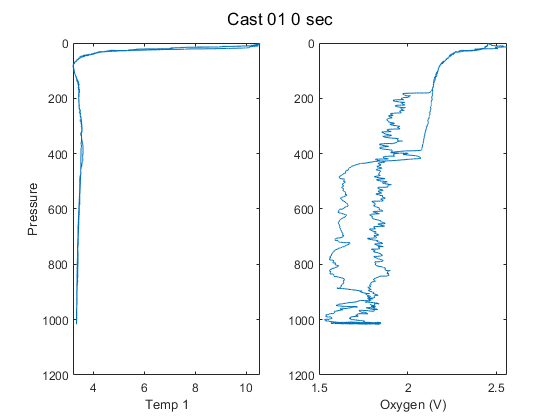

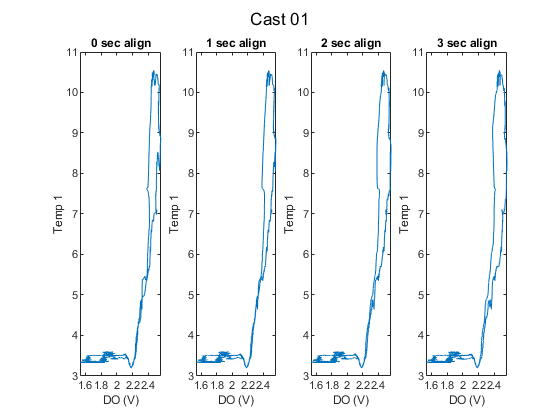

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 1; a2 = 2; a3 = 3;
cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

CTD_sen1 = 1; % Use primary or secondary CTD temp and sal
CTD_sen2 = 2; 

cast01 = align_CTD_by_sensor_KF(cast01,'Cast 01',a1,a2,a3,CTD_sen1);

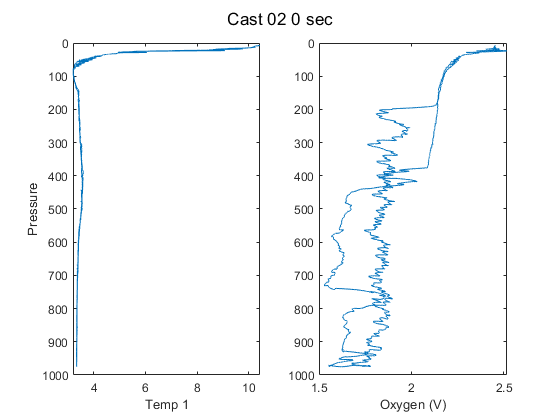

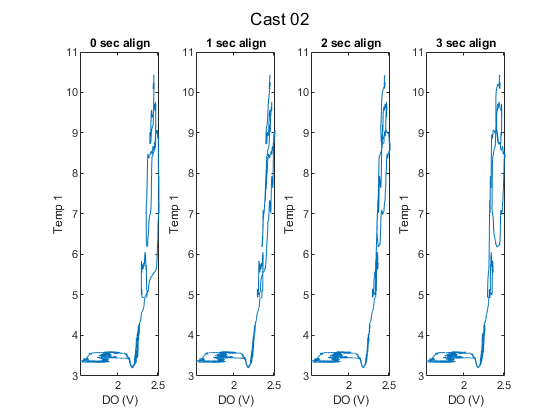

cast02 = align_CTD_by_sensor_KF(cast02,'Cast 02',a1,a2,a3,CTD_sen1);

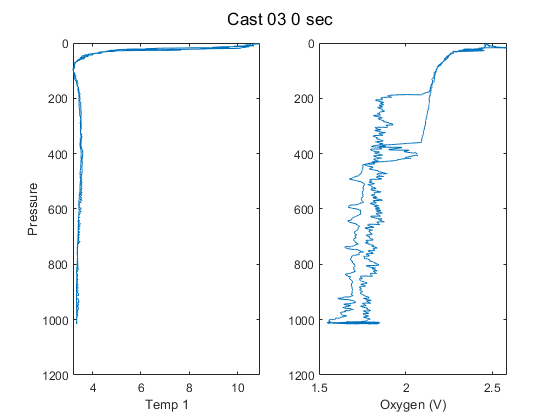

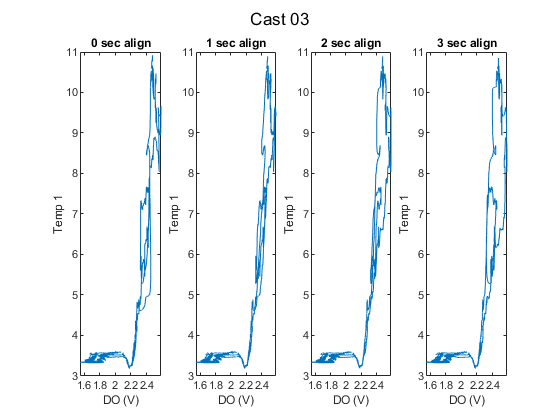

cast03 = align_CTD_by_sensor_KF(cast03,'Cast 03',a1,a2,a3,CTD_sen1);

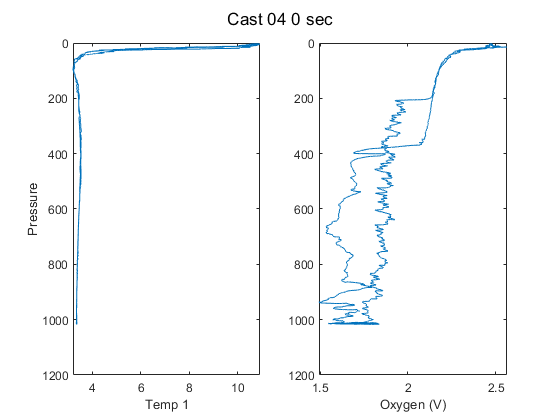

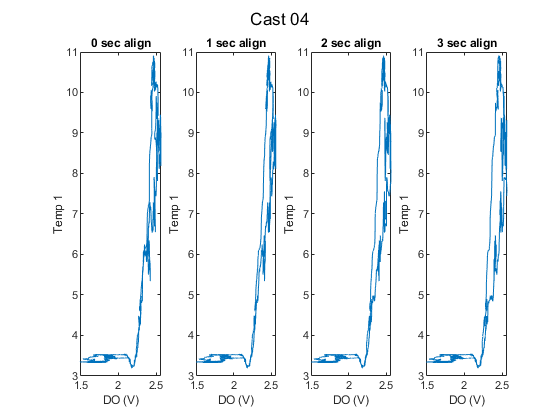

cast04 = align_CTD_by_sensor_KF(cast04,'Cast 04',a1,a2,a3,CTD_sen1);

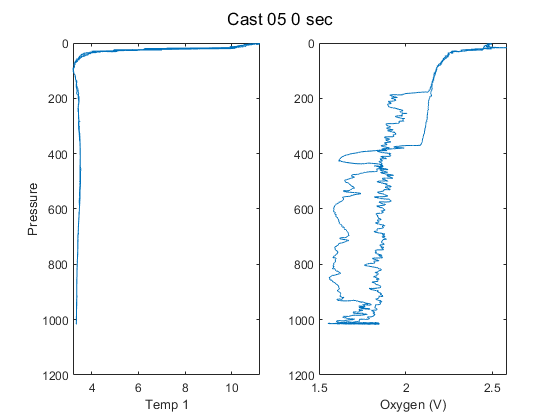

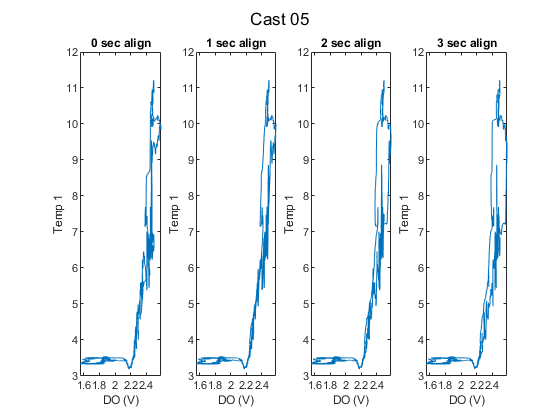

cast05 = align_CTD_by_sensor_KF(cast05,'Cast 05',a1,a2,a3,CTD_sen1);

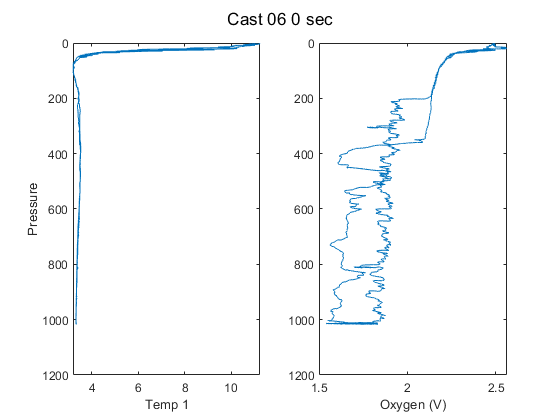

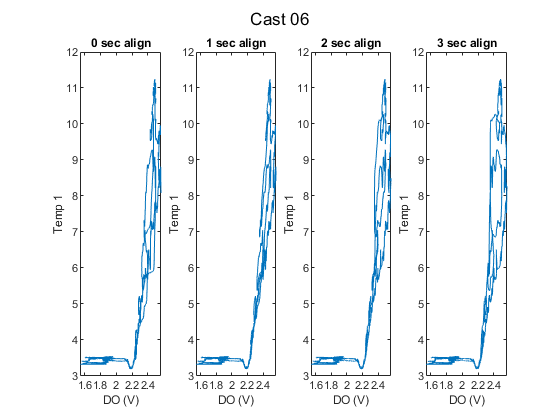

cast06 = align_CTD_by_sensor_KF(cast06,'Cast 06',a1,a2,a3,CTD_sen1);

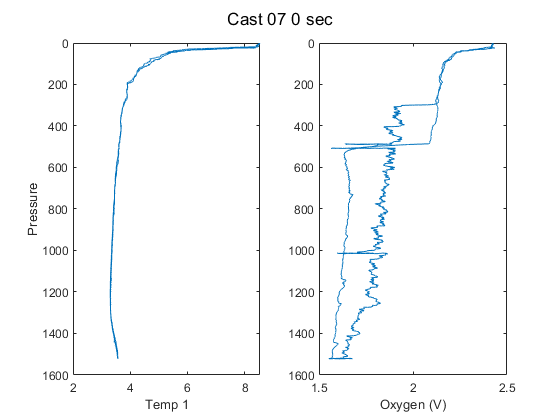

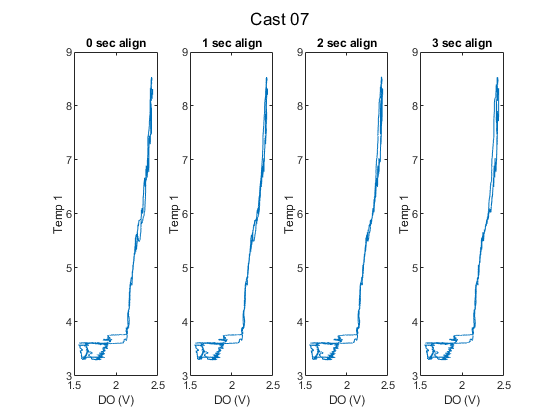

cast07 = align_CTD_by_sensor_KF(cast07,'Cast 07',a1,a2,a3,CTD_sen1);

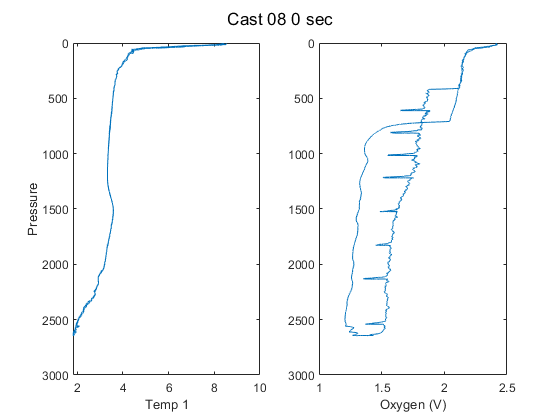

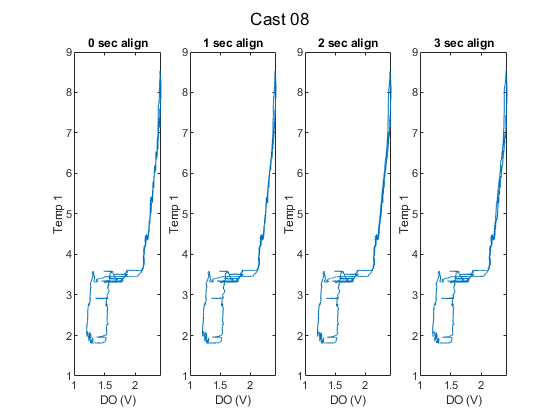

cast08 = align_CTD_by_sensor_KF(cast08,'Cast 08',a1,a2,a3,CTD_sen1);

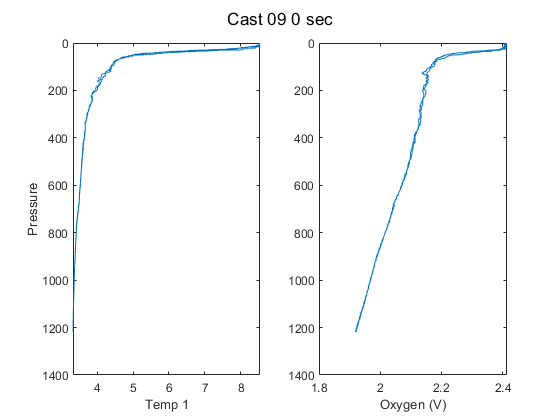

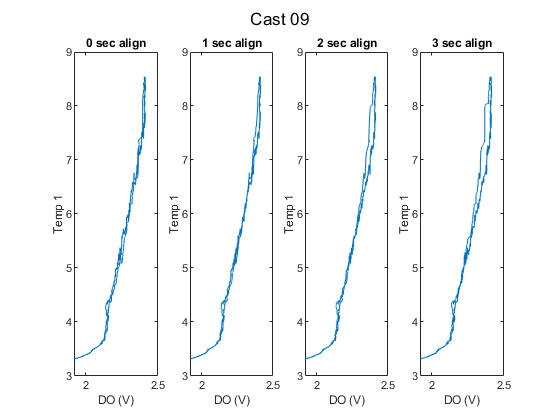

cast09 = align_CTD_by_sensor_KF(cast09,'Cast 09',a1,a2,a3,CTD_sen1);

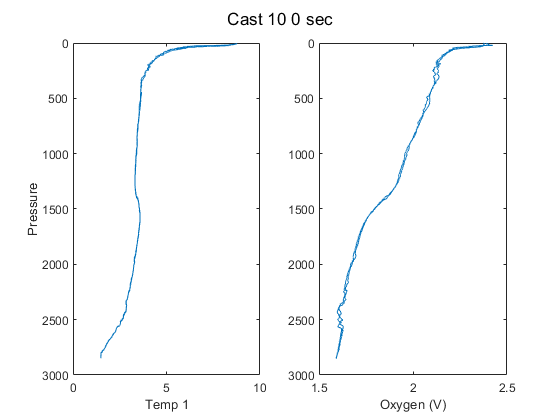

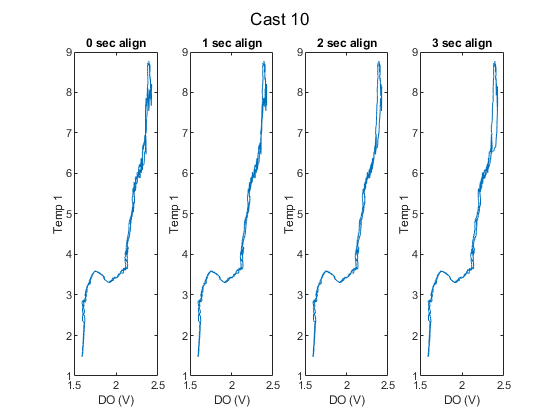

cast10 = align_CTD_by_sensor_KF(cast10,'Cast 10',a1,a2,a3,CTD_sen1);

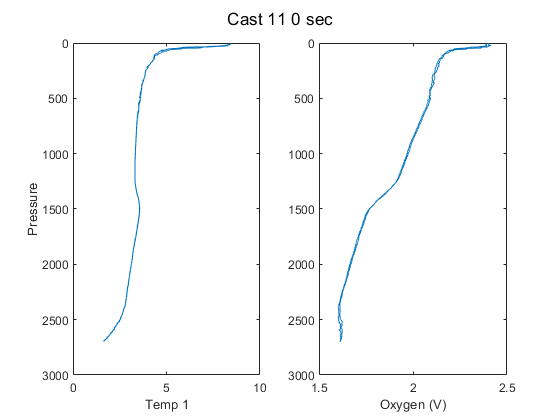

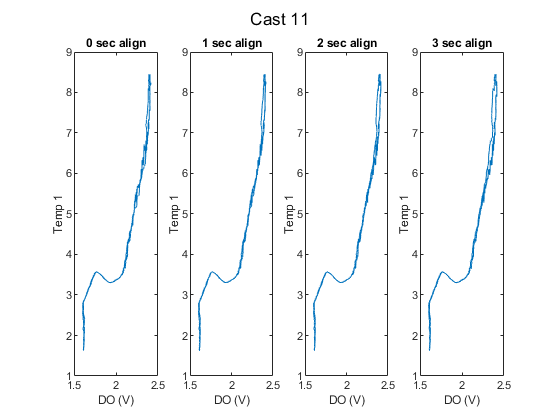

cast11 = align_CTD_by_sensor_KF(cast11,'Cast 11',a1,a2,a3,CTD_sen1);

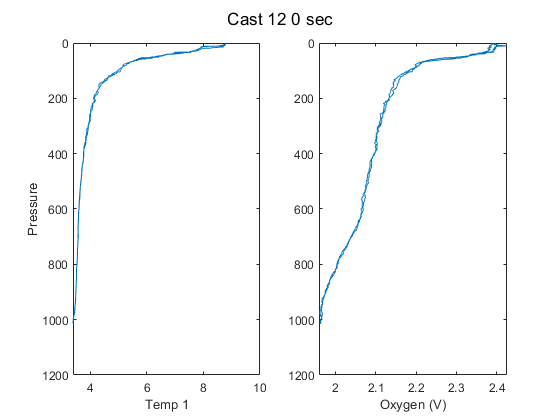

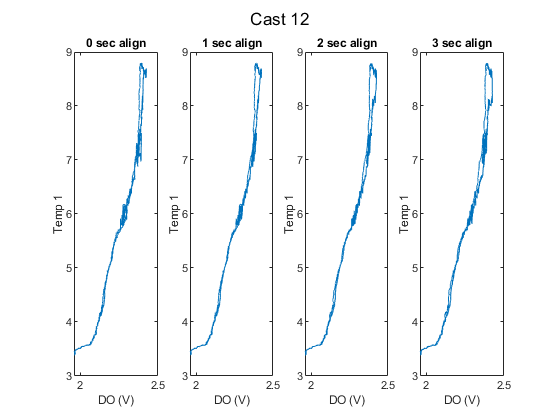

cast12 = align_CTD_by_sensor_KF(cast12,'Cast 12',a1,a2,a3,CTD_sen1);

% Pick align_sec
a1 = 0;
align_sec = a1; 

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year4')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')

btl = readtable('Irminger_Sea-04_AR21_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);

btlsum07 = combine_btl_files2('AR21_007.csv',btlsum07);

btlsum08 = combine_btl_files2('AR21_008.csv',btlsum08);

btlsum10 = combine_btl_files2('AR21_010.csv',btlsum10);

btlsum11 = combine_btl_files2('AR21_011.csv',btlsum11);

btlsum12 = combine_btl_files2('AR21_012.csv',btlsum12);


%% If get finalized finalsfrom Leah 
% btlsum02 = combine_btl_files('AR21_002.cbot_s','AR21_002.csv',btlsum02,CTD_sen1);
% btlsum03 = combine_btl_files('AR21_003.cbot_s','AR21_003.csv',btlsum03,CTD_sen1);
% btlsum04 = combine_btl_files('AR21_004.cbot_s','AR21_004.csv',btlsum04,CTD_sen1);
% btlsum05 = combine_btl_files('AR21_005.cbot_s','AR21_005.csv',btlsum05,CTD_sen1);
% btlsum06 = combine_btl_files('AR21_006.cbot_s','AR21_006.csv',btlsum06,CTD_sen1);
% btlsum07 = combine_btl_files('AR21_007.cbot_s','AR21_007.csv',btlsum07,CTD_sen1);
% btlsum09 = combine_btl_files('AR21_009.cbot_s','AR21_009.csv',btlsum09,CTD_sen1);

btlsum_yr4 = [btlsum07; btlsum08; btlsum10; btlsum11; btlsum12];
btlsum0 = [btlsum10; btlsum11; btlsum12]; %

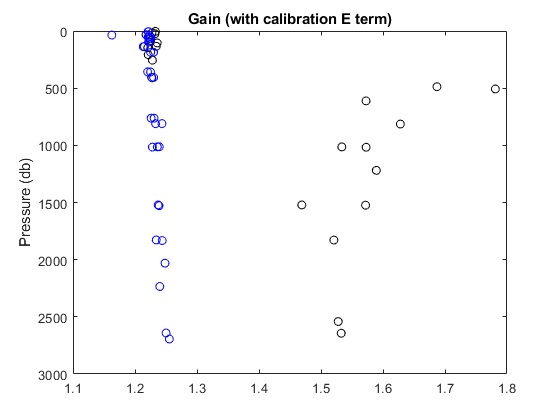

figure % Winkler/CTD Oxygen (without Leah calibrated Sal product)
plot(btlsum_yr4.Winkler_mLL./btlsum_yr4.CTDoxy_mLL,btlsum_yr4.PrDM,'ok')
hold on
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL,btlsum0.PrDM,'ob')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.61240e-001);
cal.VOFFSET = double(-5.10000e-001);
cal.A = double(-5.44340e-003);
cal.B = double(3.01750e-004);
cal.C = double(-4.29640e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.04000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0930';
cal.OCALDATE = '11-Nov-16';

H = [-0.033, 5000, 1450]; % Default 

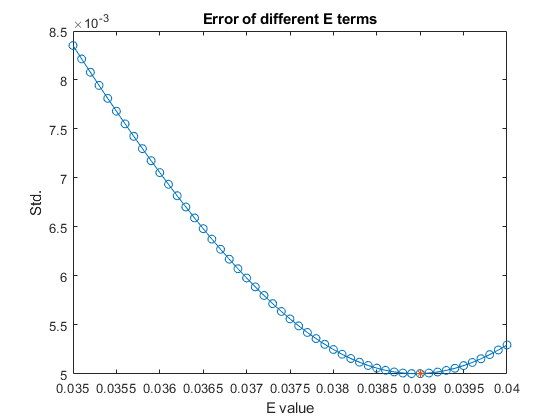

cal.E2 = 0.039


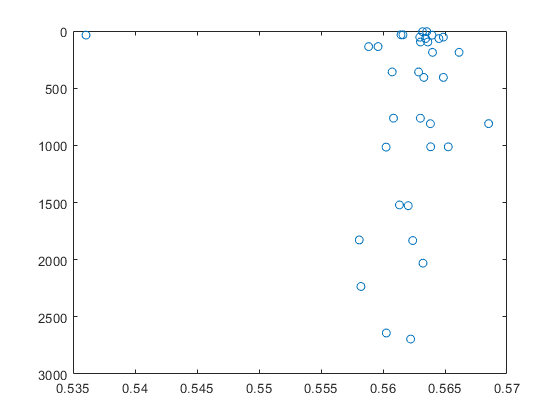

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

btlsum0.CTDoxy_mLL_cal = btlsum0.CTDoxy_mLL; % Because don't have cal product

[cal] = E2_calculation(btlsum0,cal,CTD_sen1); % Use dummy bottle summary with outlier removed

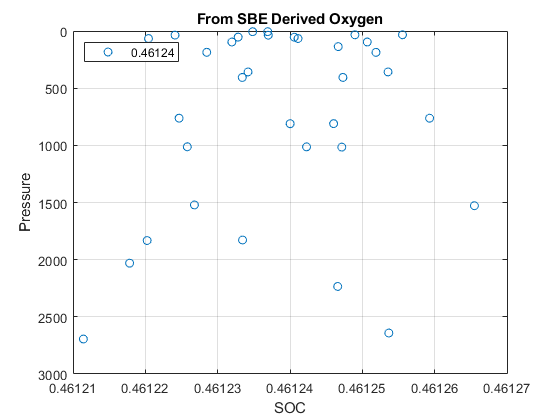

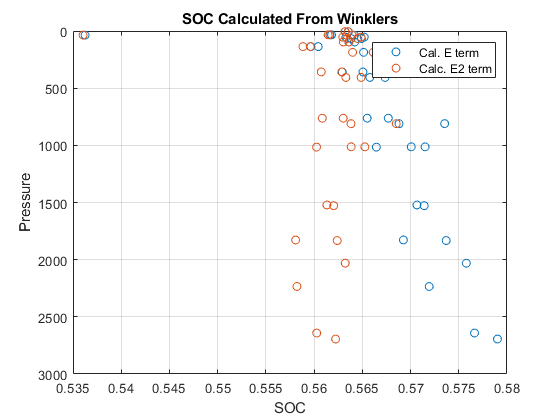

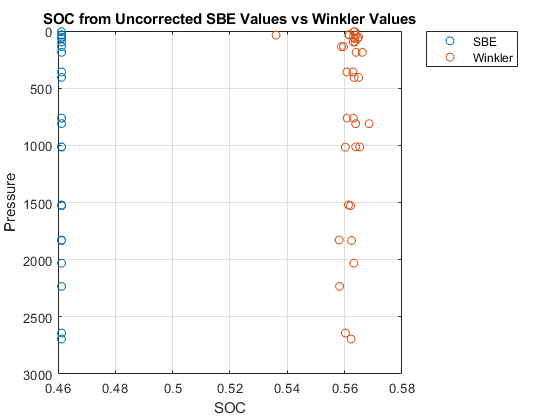

New SOC = 0.56188
EGain = 1.2182+/- 0.010849



[cal] = Gain_E2_Calculation(btlsum0,cal,CTD_sen1); % Use dummy bottle summary with any outliers removed

% Read in processed casts
% Processed with 0 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
cast01u = readSBScnv( 'uAR21_001.cnv' );
cast02u = readSBScnv( 'uAR21_002.cnv' );
cast03u = readSBScnv( 'uAR21_003.cnv' );
cast04u = readSBScnv( 'uAR21_004.cnv' );
cast05u = readSBScnv( 'uAR21_005.cnv' );
cast06u = readSBScnv( 'uAR21_006.cnv' );
cast07u = readSBScnv( 'uAR21_007.cnv' );
cast08u = readSBScnv( 'uAR21_008.cnv' );
cast09u = readSBScnv( 'uAR21_009.cnv' );
cast10u = readSBScnv( 'uAR21_010.cnv' );
cast11u = readSBScnv( 'uAR21_011.cnv' );
cast12u = readSBScnv( 'uAR21_012.cnv' );

cast01d = readSBScnv( 'dAR21_001.cnv' );
cast02d = readSBScnv( 'dAR21_002.cnv' );
cast03d = readSBScnv( 'dAR21_003.cnv' );
cast04d = readSBScnv( 'dAR21_004.cnv' );
cast05d = readSBScnv( 'dAR21_005.cnv' );
cast06d = readSBScnv( 'dAR21_006.cnv' );
cast07d = readSBScnv( 'dAR21_007.cnv' );
cast08d = readSBScnv( 'dAR21_008.cnv' );
cast09d = readSBScnv( 'dAR21_009.cnv' );
cast10d = readSBScnv( 'dAR21_010.cnv' );
cast11d = readSBScnv( 'dAR21_011.cnv' );
cast12d = readSBScnv( 'dAR21_012.cnv' );

% Format to table without Leah's product 
[cast01u, cast01u0] = combine_CTD_files2(cast01u); [cast01d, cast01d0] = combine_CTD_files2(cast01d);  
[cast02u, cast02u0] = combine_CTD_files2(cast02u); [cast02d, cast02d0] = combine_CTD_files2(cast02d);  
[cast03u, cast03u0] = combine_CTD_files2(cast03u); [cast03d, cast03d0] = combine_CTD_files2(cast03d);  
[cast04u, cast04u0] = combine_CTD_files2(cast04u); [cast04d, cast04d0] = combine_CTD_files2(cast04d);  
[cast05u, cast05u0] = combine_CTD_files2(cast05u); [cast05d, cast05d0] = combine_CTD_files2(cast05d);  
[cast06u, cast06u0] = combine_CTD_files2(cast06u); [cast06d, cast06d0] = combine_CTD_files2(cast06d);  
[cast07u, cast07u0] = combine_CTD_files2(cast07u); [cast07d, cast07d0] = combine_CTD_files2(cast07d);  
[cast08u, cast08u0] = combine_CTD_files2(cast08u); [cast08d, cast08d0] = combine_CTD_files2(cast08d);  
[cast09u, cast09u0] = combine_CTD_files2(cast09u); [cast09d, cast09d0] = combine_CTD_files2(cast09d);  
[cast10u, cast10u0] = combine_CTD_files2(cast10u); [cast10d, cast10d0] = combine_CTD_files2(cast10d); 
[cast11u, cast11u0] = combine_CTD_files2(cast11u); [cast11d, cast11d0] = combine_CTD_files2(cast11d); 
[cast12u, cast12u0] = combine_CTD_files2(cast12u); [cast12d, cast12d0] = combine_CTD_files2(cast12d); 


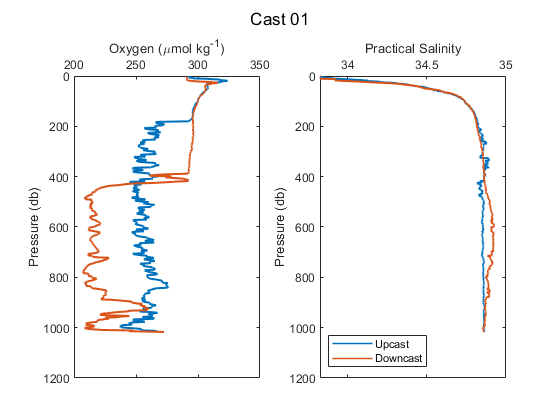

% Using function written for missing final Sal product 
sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_v3(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)

[cast01u, cast01d, btlsum01] = Process_Cast_Gain_E2_v3(cast01u,cast01d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 01');

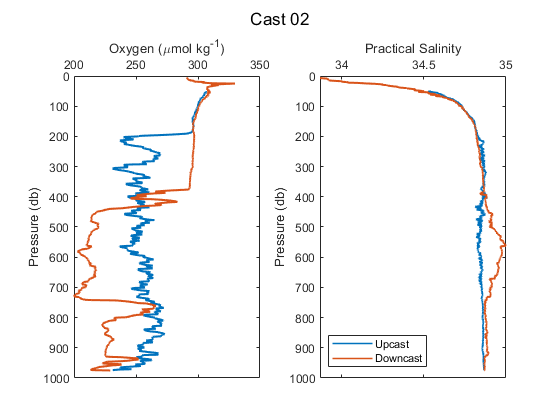

[cast02u, cast02d, btlsum02] = Process_Cast_Gain_E2_v3(cast02u,cast02d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 02');

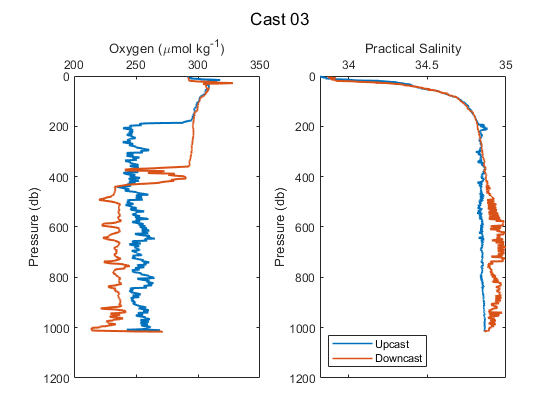

[cast03u, cast03d, btlsum03] = Process_Cast_Gain_E2_v3(cast03u,cast03d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 03');

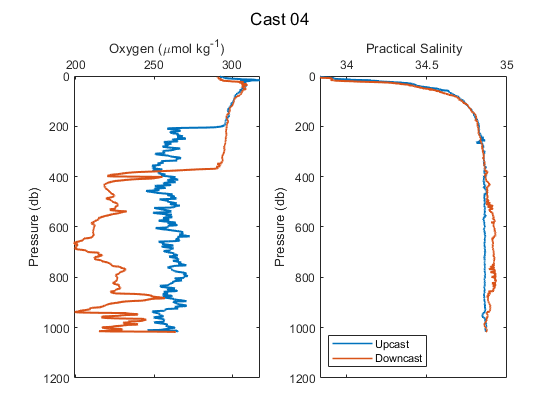

[cast04u, cast04d, btlsum04] = Process_Cast_Gain_E2_v3(cast04u,cast04d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 04');

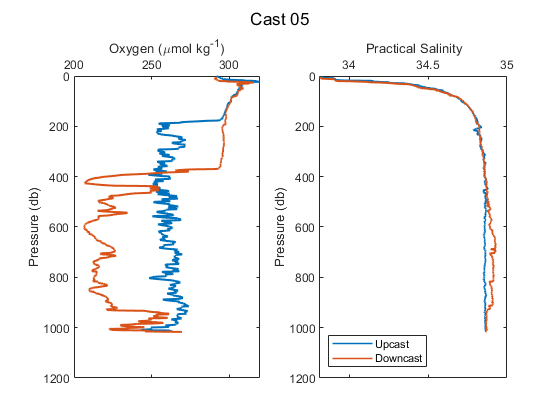

[cast05u, cast05d, btlsum05] = Process_Cast_Gain_E2_v3(cast05u,cast05d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 05');

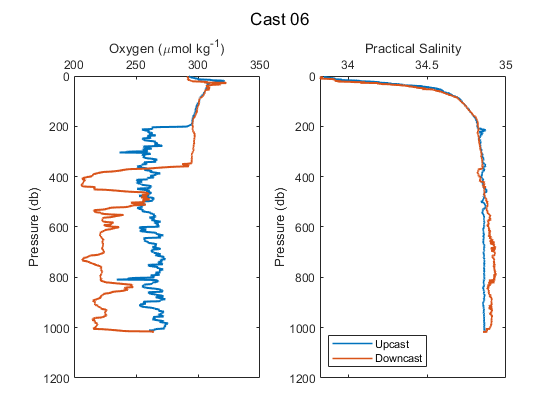

[cast06u, cast06d, btlsum06] = Process_Cast_Gain_E2_v3(cast06u,cast06d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 06');

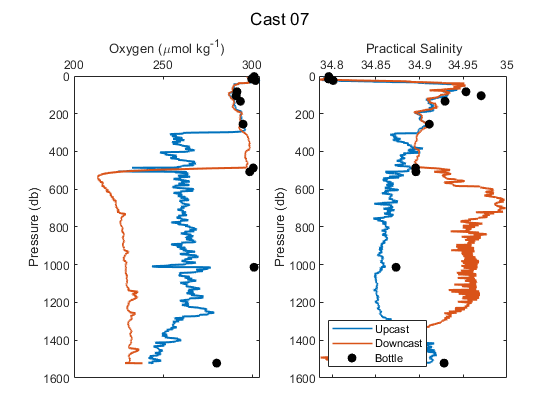

[cast07u, cast07d, btlsum07] = Process_Cast_Gain_E2_v3(cast07u,cast07d,cal,btlsum07,sal_plots,leah_plot,CTD_sen1,'Cast 07');

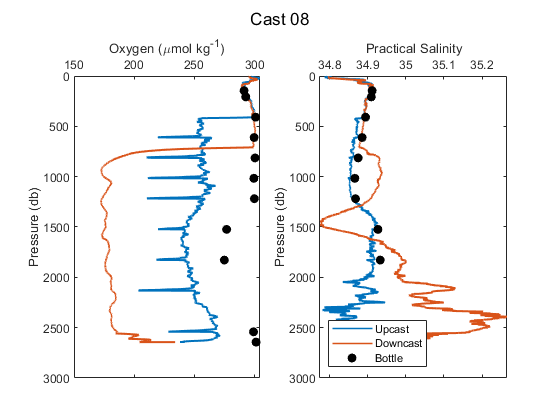

[cast08u, cast08d, btlsum08] = Process_Cast_Gain_E2_v3(cast08u,cast08d,cal,btlsum08,sal_plots,leah_plot,CTD_sen1,'Cast 08');

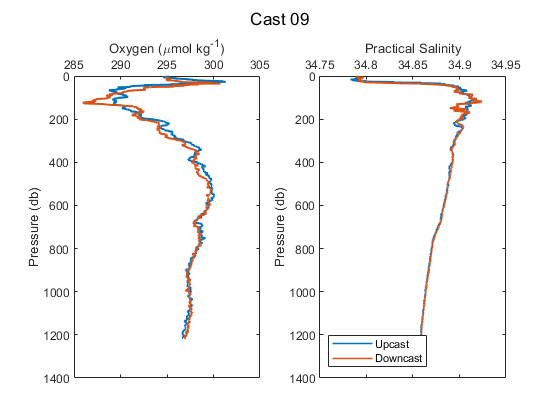

[cast09u, cast09d, btlsum09] = Process_Cast_Gain_E2_v3(cast09u,cast09d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 09');

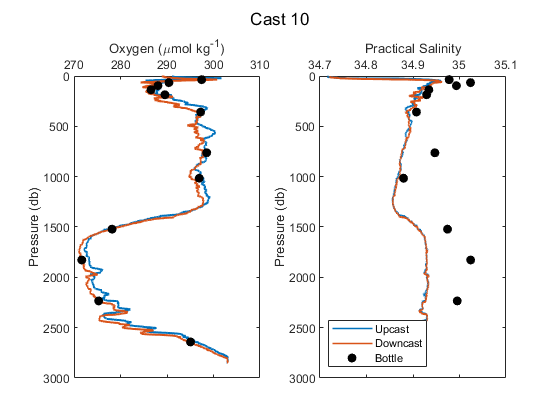

[cast10u, cast10d, btlsum10] = Process_Cast_Gain_E2_v3(cast10u,cast10d,cal,btlsum10,sal_plots,leah_plot,CTD_sen1,'Cast 10');

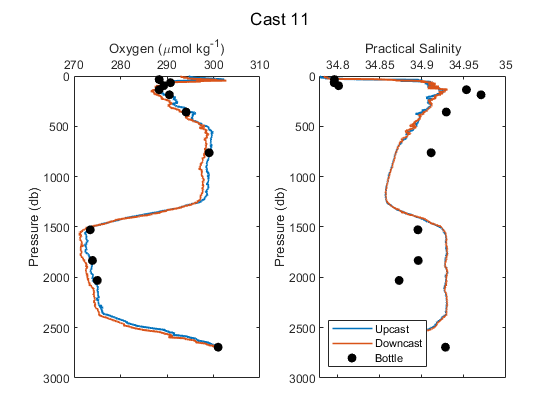

[cast11u, cast11d, btlsum11] = Process_Cast_Gain_E2_v3(cast11u,cast11d,cal,btlsum11,sal_plots,leah_plot,CTD_sen1,'Cast 11');

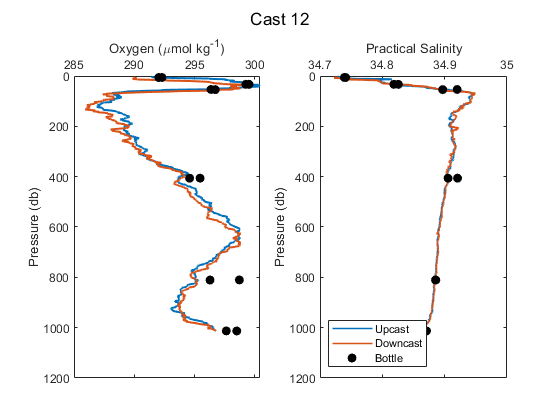

[cast12u, cast12d, btlsum12] = Process_Cast_Gain_E2_v3(cast12u,cast12d,cal,btlsum12,sal_plots,leah_plot,CTD_sen1,'Cast 12');

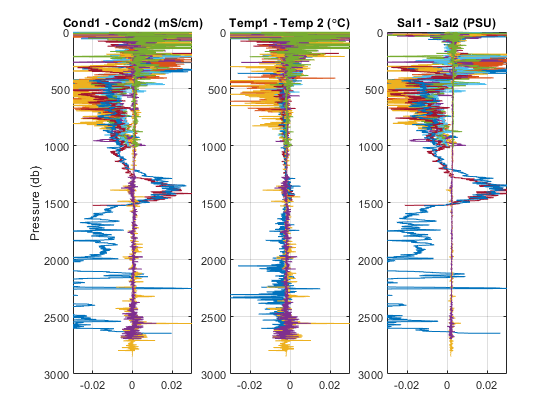

figure
subplot(1,3,1)
plot(cast01u.cond1-cast01u.cond2,cast01u.prs)
hold on
plot(cast02u.cond1-cast02u.cond2,cast02u.prs)
plot(cast03u.cond1-cast03u.cond2,cast03u.prs)
plot(cast04u.cond1-cast04u.cond2,cast04u.prs)
plot(cast05u.cond1-cast05u.cond2,cast05u.prs)
plot(cast06u.cond1-cast06u.cond2,cast06u.prs)
plot(cast07u.cond1-cast07u.cond2,cast07u.prs)
plot(cast08u.cond1-cast08u.cond2,cast08u.prs)
plot(cast09u.cond1-cast09u.cond2,cast09u.prs)
plot(cast10u.cond1-cast10u.cond2,cast10u.prs)
plot(cast11u.cond1-cast11u.cond2,cast11u.prs)
plot(cast12u.cond1-cast12u.cond2,cast12u.prs)
axis ij
grid on
xlim([-0.03 0.03])
ylabel('Pressure (db)')
title('Cond1 - Cond2 (mS/cm)')

subplot(1,3,2)
plot(cast01u.temp1-cast01u.temp2,cast01u.prs)
hold on
plot(cast02u.temp1-cast02u.temp2,cast02u.prs)
plot(cast03u.temp1-cast03u.temp2,cast03u.prs)
plot(cast04u.temp1-cast04u.temp2,cast04u.prs)
plot(cast05u.temp1-cast05u.temp2,cast05u.prs)
plot(cast06u.temp1-cast06u.temp2,cast06u.prs)
plot(cast07u.temp1-cast07u.temp2,cast07u.prs)
plot(cast08u.temp1-cast08u.temp2,cast08u.prs)
plot(cast09u.temp1-cast09u.temp2,cast09u.prs)
plot(cast10u.temp1-cast10u.temp2,cast10u.prs)
plot(cast11u.temp1-cast11u.temp2,cast11u.prs)
plot(cast12u.temp1-cast12u.temp2,cast12u.prs)
axis ij
grid on
xlim([-0.03 0.03])
title('Temp1 - Temp 2 (\circC)')

subplot(1,3,3)
plot(cast01u.sal1-cast01u.sal2,cast01u.prs)
hold on
plot(cast02u.sal1-cast02u.sal2,cast02u.prs)
plot(cast03u.sal1-cast03u.sal2,cast03u.prs)
plot(cast04u.sal1-cast04u.sal2,cast04u.prs)
plot(cast05u.sal1-cast05u.sal2,cast05u.prs)
plot(cast06u.sal1-cast06u.sal2,cast06u.prs)
plot(cast07u.sal1-cast07u.sal2,cast07u.prs)
plot(cast08u.sal1-cast08u.sal2,cast08u.prs)
plot(cast09u.sal1-cast09u.sal2,cast09u.prs)
plot(cast10u.sal1-cast10u.sal2,cast10u.prs)
plot(cast11u.sal1-cast11u.sal2,cast11u.prs)
plot(cast12u.sal1-cast12u.sal2,cast12u.prs)
axis ij
grid on
xlim([-0.03 0.03])
title('Sal1 - Sal2 (PSU)')

btlsum_yr4 = [btlsum07; btlsum08; btlsum10; btlsum11; btlsum12];
btlsum_yr4_OOI = btlsum_yr4; 

disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 0


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term (E2) = ' num2str(cal.E2)])

Adjust. E term (E2) = 0.039


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.46124


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.56188


disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])

E2Gain = 1.2182+/- 0.010849


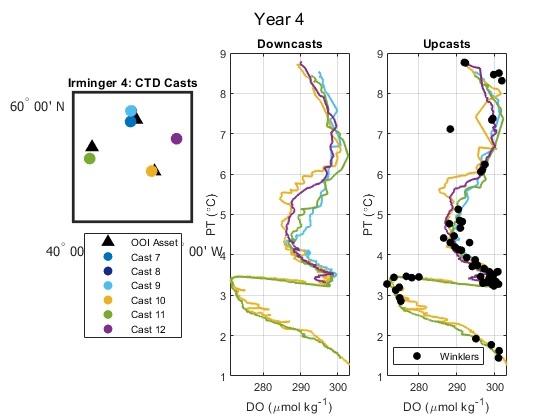

run('Year4_PT_DO_plots.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
clear btlsum0
dt_Processed = datetime;
save Year4_Processed_KF cast* btl* cal* dt_Processed 